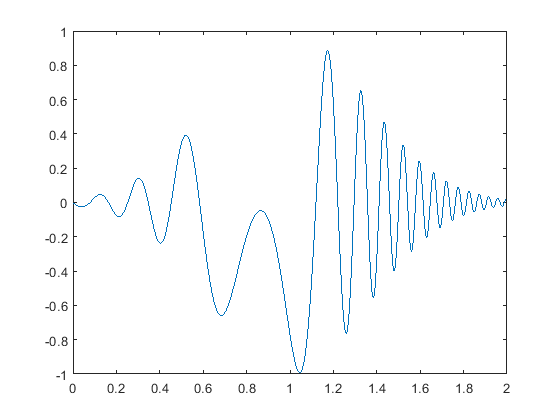

fs = 2000;
t = 0:1/fs:2-1/fs;
q = chirp(t-2,4,1/2,6,'quadratic',100,'convex').*exp(-4*(t-1).^2);

figure()
plot(t,q)

hilbertHuangTransformer = HilbertHuangTransform();

[intrinsicModes, residue] = hilbertHuangTransformer.getIntrinsicModeFunctions(q, 3, 20);

     0

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

     0

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

     0



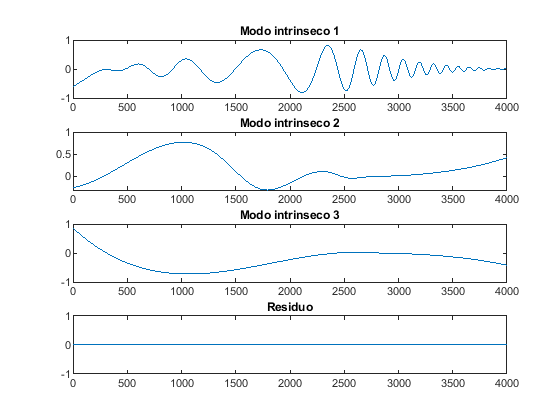

figure()
hold on 
for i = 1:length(intrinsicModes)
    intrinsicMode = intrinsicModes{i};
    subplot(length(intrinsicModes) + 1,1,i);
    plot(intrinsicMode)
    title("Modo intrinseco "+string(i))
end

subplot(length(intrinsicModes) +1,1,length(intrinsicModes) + 1)
plot(residue)
title("Residuo")

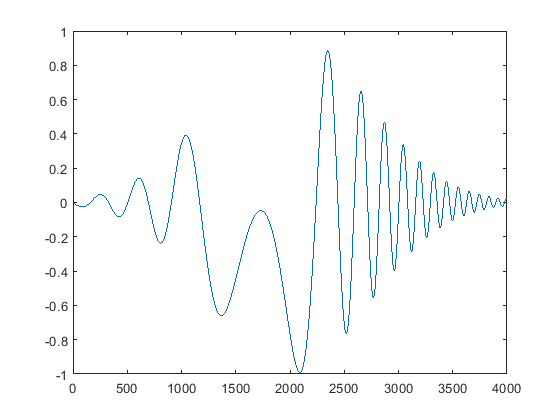

sumIntrisicModes = residue + intrinsicModes{1} + intrinsicModes{2} + intrinsicModes{3};
figure()
plot(sumIntrisicModes);